## Part 1 )

%% Parameters
m = 0.27;
r = 0.02;
b = 1;
K = 10^-3;
l = 0.49;
Jw = 14.025*10^-2;
Jb = 4.32*10^-5;
g = 9.81;


%% Equations
syms u x1 x2 x_dot_2 x3 x4 x_dot_4
eq1 = (Jb/r^2+m)*x_dot_2 + x_dot_4*(m*r^2+Jb)/r - m*x1*x4^2 == m*g*sin(x3);
eq2 = (m*x1^2+Jb+Jw)*x_dot_4 + (2*m*x2*x1 + b*l^2)*x4 + x3*K*l^2 + x_dot_2*(m*r^2 + Jb)/r - m*g*x1*cos(x3) == u*l*cos(x3);
eqns = [eq1, eq2];

S = solve([eq1, eq2],[x_dot_2 x_dot_4]);
S.x_dot_2

$$ans = \frac{144115188075855872\,\left(498062089990157893632000\,{x_{1}}^{3}\,{x_{4}}^{2}+4885989102803448936529920\,\sin\left(x_{3}\right)\,{x_{1}}^{2}+258795275568174886676900\,x_{1}\,{x_{4}}^{2}+27891477039448845000000\,x_{2}\,x_{1}\,x_{4}-136807694878496584725000\,\cos\left(x_{3}\right)\,x_{1}+12401377105873458675000\,x_{4}+12401377105873458675\,x_{3}+2538781653323795638300389\,\sin\left(x_{3}\right)-25308932869129507500000\,u\,\cos\left(x_{3}\right)\right)}{5\,\left(20097927296267927998305562751438809989120\,{x_{1}}^{2}+10431717507976222092181648289816026595029\right)}$$

S.x_dot_4

$$ans = -\frac{1152921504606846976\,\left(9688575863963638562816\,x_{3}+9688575863963638562816000\,x_{4}+2137620232476509136328125\,\sin\left(x_{3}\right)+217902164370694101562500\,x_{1}\,{x_{4}}^{2}-19772603804007425638400000\,u\,\cos\left(x_{3}\right)-106881011623825445486592000\,x_{1}\,\cos\left(x_{3}\right)+21790216437069407846400000\,x_{1}\,x_{2}\,x_{4}\right)}{625\,\left(20097927296267927998305562751438809989120\,{x_{1}}^{2}+10431717507976222092181648289816026595029\right)}$$

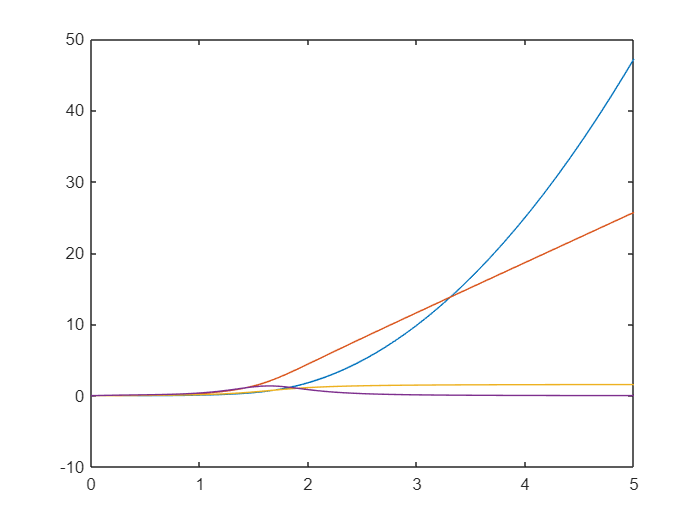

%% Verification
tspan = [0 5];
x0 = [0 0 0 0];
[t,x] = ode45(@(t,x) odefcn(t,x), tspan, x0);

plot(t,x(:,1),t,x(:,2),t,x(:,3),t,x(:,4))

## Part 2)

%% Linearization
format long
f2_linear_to_x1(x1,x2,x3,x4,u) = diff(S.x_dot_2,x1);
f2_linear_to_x2(x1,x2,x3,x4,u) = diff(S.x_dot_2,x2);
f2_linear_to_x3(x1,x2,x3,x4,u) = diff(S.x_dot_2,x3);
f2_linear_to_x4(x1,x2,x3,x4,u) = diff(S.x_dot_2,x4);
f4_linear_to_x1(x1,x2,x3,x4,u) = diff(S.x_dot_4,x1);
f4_linear_to_x2(x1,x2,x3,x4,u) = diff(S.x_dot_4,x2);
f4_linear_to_x3(x1,x2,x3,x4,u) = diff(S.x_dot_4,x3);
f4_linear_to_x4(x1,x2,x3,x4,u) = diff(S.x_dot_4,x4);
f2_linear_to_u(x1,x2,x3,x4,u) = diff(S.x_dot_2,u);
f4_linear_to_u(x1,x2,x3,x4,u) = diff(S.x_dot_4,u);
a21 = double(f2_linear_to_x1(0,0,0,0,0))

a21 =   -0.378002311940746


a22 = double(f2_linear_to_x2(0,0,0,0,0))

a22 =      0


a23 = double(f2_linear_to_x3(0,0,0,0,0))

a23 =    7.014737168626923


a24 = double(f2_linear_to_x4(0,0,0,0,0))

a24 =    0.034265245251245


a41 = double(f4_linear_to_x1(0,0,0,0,0))

a41 =   18.900115597037292


a42 = double(f4_linear_to_x2(0,0,0,0,0))

a42 =      0


a43 = double(f4_linear_to_x3(0,0,0,0,0))

a43 =   -0.379715574203308


a44 = double(f4_linear_to_x4(0,0,0,0,0))

a44 =   -1.713262262562258


b21 = double(f2_linear_to_u(0,0,0,0,0))

b21 =   -0.069929071941317


b41 = double(f4_linear_to_u(0,0,0,0,0))

b41 =    3.496453597065833


%% Linearized State Space Equations
A = [0,1,0,0;a21,0,a23,a24;0,0,0,1;a41,0,a43,a44];
B = [0;b21;0;b41];
C = [1,0,0,0;0,0,1,0];
D = [0;0];

## Part 3)

%% Stability Investigation
lambda = eig(A)

lambda =    2.9896 + 0.0000i
  -3.8454 + 0.0000i
  -0.4288 + 3.3669i
  -0.4288 - 3.3669i


## Part 4)

%% Controlability
c = [B,A*B,A^2*B,A^3*B]

c =          0   -0.0699    0.1198   24.3479
   -0.0699    0.1198   24.3479  -41.8051
         0    3.4965   -5.9903    7.6137
    3.4965   -5.9903    7.6137   -8.5053


rank(c)

ans =      4


%% Observability
o = [C;C*A;C*A^2;C*A^3]

o =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
   -0.3780         0    7.0147    0.0343
   18.9001         0   -0.3797   -1.7133
    0.6476   -0.3780   -0.0130    6.9560
  -32.3809   18.9001    0.6506    2.5556


rank(o)

ans =      4


%% Minimality
det(A)

ans =     -1.324358100049542e+02


## Part 5)

%% State Transformation Matrix
[Q,J] = eig(A)

Q =    0.1926 + 0.0000i  -0.1040 + 0.0000i  -0.0546 - 0.1400i  -0.0546 + 0.1400i
   0.5757 + 0.0000i   0.4000 + 0.0000i   0.4947 - 0.1239i   0.4947 + 0.1239i
   0.2521 + 0.0000i  -0.2292 + 0.0000i   0.0302 + 0.2375i   0.0302 - 0.2375i
   0.7536 + 0.0000i   0.8813 + 0.0000i  -0.8125 + 0.0000i  -0.8125 + 0.0000i


J =    2.9896 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -3.8454 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4288 + 3.3669i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4288 - 3.3669i


e_At = Q*[exp(0.1926),0,0,0;0,exp(-3.8454),0,0;0,0,exp(-0.4288+3.3669i),0;0,0,0,exp(-0.4288-3.3669i)]*inv(Q)

e_At =    0.0006 - 0.0000i   0.1121 - 0.0000i   0.4665 + 0.0000i   0.0680 - 0.0000i
   1.2424 - 0.0000i   0.0006 + 0.0000i   0.7606 + 0.0000i   0.3539 - 0.0000i
   0.9514 - 0.0000i   0.1785 + 0.0000i   0.0005 + 0.0000i   0.0259 - 0.0000i
   0.4212 - 0.0000i   0.9514 + 0.0000i   1.2423 + 0.0000i  -0.0376 + 0.0000i


## Part 6)

%% Transformation Function
G = tf(ss(A,B,C,D))

G =
 
  From input to output...
               -0.06993 s^2 + 9.938e-16 s + 24.5
   1:  --------------------------------------------------
       s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
                     3.496 s^2 - 2.747e-16
   2:  --------------------------------------------------
       s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.



%% System Zeros, Poles and Gain
G1_num = [0 0 -0.06993 0 24.5];
G2_num = [0 0 3.496 0 0];
G_dem = [1 1.713 0.7577 7.105e-15 -132.4];

[z1, p1, k1] = tf2zp(G1_num, G_dem)

z1 =    18.7176
  -18.7176


p1 =   -3.8450 + 0.0000i
  -0.4287 + 3.3667i
  -0.4287 - 3.3667i
   2.9894 + 0.0000i


k1 =   -0.069930000000000


[z2, p2, k2] = tf2zp(G2_num, G_dem)

z2 =      0
     0


p2 =   -3.8450 + 0.0000i
  -0.4287 + 3.3667i
  -0.4287 - 3.3667i
   2.9894 + 0.0000i


k2 =    3.496000000000000


## Part 7)

%% PID Controller Design and results
G1_approximate = tf(G1_num,G_dem)

G1_approximate =
 
                 -0.06993 s^2 + 24.5
  --------------------------------------------------
  s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.



G2_approximate = tf(G2_num,G_dem)

G2_approximate =
 
                      3.496 s^2
  --------------------------------------------------
  s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.



pidTuner(G1_approximate,'PID') 
pidTuner(G2_approximate,'PID') 
[C_PID_1_approximate,G1_approximate_info] = pidtune(G1_approximate,'PID')

C_PID_1_approximate =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.093, Ki = 0.00258, Kd = 0.837
 
Continuous-time PID controller in parallel form.



G1_approximate_info = struct with fields:
                Stable: 0
    CrossoverFrequency: 3.173606324483949
           PhaseMargin: NaN


[C_PID_2_approximate,G2_approximate_info] = pidtune(G2_approximate,'PID')

C_PID_2_approximate =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 2.77e+03, Ki = 3.33e+04, Kd = 57.7
 
Continuous-time PID controller in parallel form.



G2_approximate_info = struct with fields:
                Stable: 0
    CrossoverFrequency: 2.045219704308076e+02
           PhaseMargin: NaN



s = tf('s');
G1_cl = minreal(((0.093+33300/s+57.7*s)*(G1_approximate))/(1+(0.093+33300/s+57.7*s)*(G1_approximate)))

G1_cl =
 
   -4.035 s^4 - 0.006503 s^3 - 915 s^2 + 2.278 s + 8.158e05
  -----------------------------------------------------------
  s^5 - 2.322 s^4 + 0.7512 s^3 - 915 s^2 - 130.1 s + 8.159e05
 
Continuous-time transfer function.



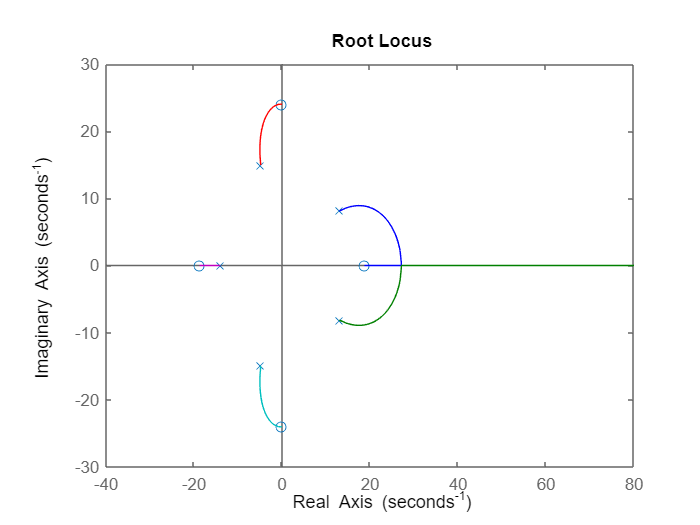

rlocus(G1_cl)

## Part 8)

p1_improved = p1(1:3);
p2_improved = p2(1:3)

p2_improved =   -3.8450 + 0.0000i
  -0.4287 + 3.3667i
  -0.4287 - 3.3667i


G1_improved = zpk(z1,p1_improved,k1)

G1_improved =
 
    -0.06993 (s-18.72) (s+18.72)
  ---------------------------------
  (s+3.845) (s^2 + 0.8574s + 11.52)
 
Continuous-time zero/pole/gain model.



G2_improved = zpk(z2,p2_improved,k2)

G2_improved =
 
              3.496 s^2
  ---------------------------------
  (s+3.845) (s^2 + 0.8574s + 11.52)
 
Continuous-time zero/pole/gain model.



pidTuner(G1_improved,'PID') 
pidTuner(G2_improved,'PID') 
[C_PID_1_improved,G1_improved_info] = pidtune(G1_improved,'PID')

C_PID_1_improved =
 
        1 
  Ki * ---
        s 

  with Ki = 0.79
 
Continuous-time I-only controller.



G1_improved_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.441845707701501
           PhaseMargin: 81.528516592362379


[C_PID_2_improved,G2_improved_info] = pidtune(G2_improved,'PID')

C_PID_2_improved =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 48.4, Ki = 4.02e+03, Kd = 0.0401
 
Continuous-time PID controller in parallel form.



G2_improved_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.777615127234068e+02
           PhaseMargin: 73.789642253631811


A_improved = [0,1,0;0,0,1;-44.09244,-14.816703,-4.7024];
B_improved = [0;0;1];
C_improved = [24.506157312,0,-0.06993];
D_improved = 0;
c_improved = [B_improved, A_improved*B_improved, A_improved^2*B_improved]

c_improved =          0         0    1.0000
         0    1.0000   -4.7024
    1.0000   -4.7024    7.2959


o_improved = [C_improved; C_improved*A_improved; C_improved*A_improved^2]

o_improved =    24.5062         0   -0.0699
    3.0834   25.5423    0.3288
  -14.4993   -1.7889   23.9960


## * Function Definition 

function dxdt = odefcn(t,x)
  x1 = x(1);
  x2 = x(2);
  x3 = x(3);
  x4 = x(4);
  u = zeros(size(t));
  u(t>=0) = 0.1;
  dxdt = zeros(4,1);
  dxdt(1) = x2;
  dxdt(3) = x4;
  dxdt(2) = (144115188075855872*(498062089990157893632000*x4^2*x1^3 + ...
  258795275568174886676900*x4^2*x1 + 27891477039448845000000*x2*x4*x1 + 12401377105873458675000*x4 +...
  4885989102803448936529920*sin(x3)*x1^2 - 136807694878496584725000*cos(x3)*x1 + 12401377105873458675*x3 - 25308932869129507500000*u*cos(x3) +...
  2538781653323795638300389*sin(x3)))/(5*(20097927296267927998305562751438809989120*x1^2 + 10431717507976222092181648289816026595029));
  dxdt(4) = -(1152921504606846976*(9688575863963638562816*x3 + 9688575863963638562816000*x4 -...
      19772603804007425638400000*u*cos(x3) + 2137620232476509136328125*sin(x3) + 217902164370694101562500*x4^2*x1 -...
      106881011623825445486592000*x1*cos(x3) + 21790216437069407846400000*x4*x1*x2))/(625*(20097927296267927998305562751438809989120*x1^2 +...
      10431717507976222092181648289816026595029));
end